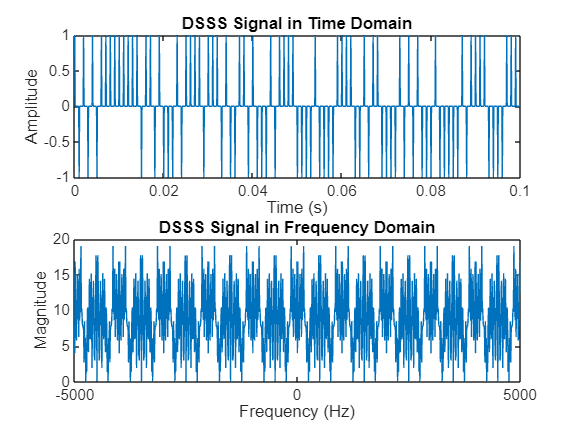

% Define parameters
dataRate = 1e3;           % Data rate in bits per second
samplingFreq = 10e3;      % Sampling frequency in Hz
numBits = 100;            % Number of bits to transmit
pnSeqLength = 127;        % Length of the PN sequence (should be a power of 2 - 1)

% Generate random binary data sequence
dataSeq = randi([0 1], 1, numBits);

% Generate PN sequence using a simple LFSR
lfsr = ones(1, 7); % Initial state of LFSR (7 bits for 127 length sequence)
pnSequence = zeros(1, pnSeqLength);
for i = 1:pnSeqLength
    pnSequence(i) = lfsr(end);
    feedback = xor(lfsr(7), lfsr(3)); % Feedback taps at positions 7 and 3
    lfsr = [feedback lfsr(1:end-1)];
end

% Repeat the PN sequence to match the length of the data sequence
pnSequenceRep = repmat(pnSequence, 1, ceil(numBits / length(pnSequence)));
pnSequenceRep = pnSequenceRep(1:numBits);

% Spread the data sequence using XOR operation
spreadData = xor(dataSeq, pnSequenceRep);

% BPSK Modulation
bpskModulated = 2*spreadData - 1; % Convert 0 to -1 and 1 to 1

% Up-sample the modulated signal
upsampledSignal = upsample(bpskModulated, samplingFreq/dataRate);

% Carrier frequency
carrierFreq = 2e3; % Carrier frequency in Hz

% Generate time vector
t = (0:length(upsampledSignal)-1) / samplingFreq;

% Modulate the spread signal onto the carrier
carrierSignal = cos(2*pi*carrierFreq*t);
modulatedSignal = upsampledSignal .* carrierSignal;

% Plot the resulting signal in time domain
figure;
subplot(2,1,1);
plot(t, modulatedSignal);
title('DSSS Signal in Time Domain');
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the resulting signal in frequency domain
subplot(2,1,2);
nfft = length(modulatedSignal);
f = (-nfft/2:nfft/2-1) * (samplingFreq/nfft);
modulatedSignalFFT = fftshift(fft(modulatedSignal, nfft));
plot(f, abs(modulatedSignalFFT));
title('DSSS Signal in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Magnitude');